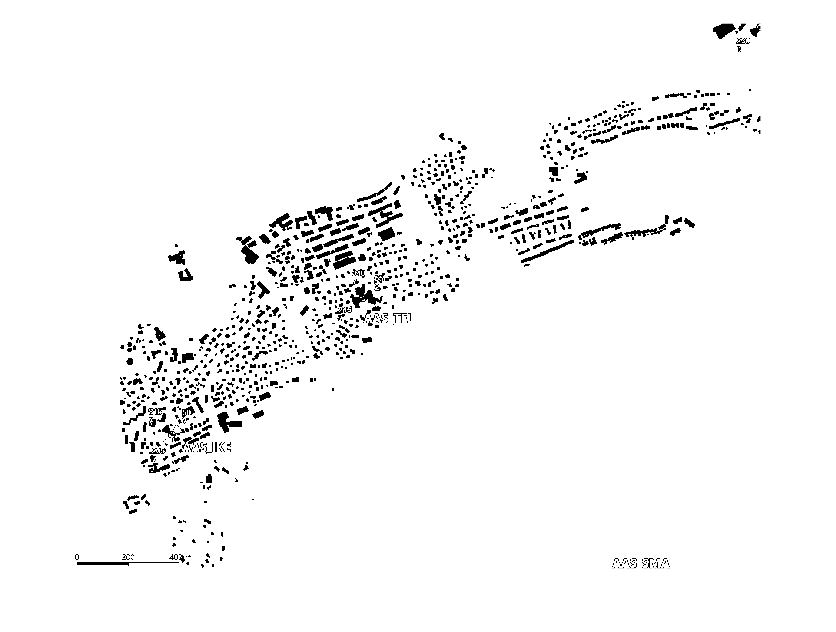

n78img = imread('aas n78 sigV2 cropped.png');
b3img = imread("aas b3 sigV2 cropped.png");
Igrn78 = rgb2gray(n78img);
Igrb3 = rgb2gray(b3img);
[X, map] = gray2ind(Igrb3, 64);
indices = find(abs(X)>35);
X(indices) = 255;

indices2 = find(abs(X)<35);
X(indices2) = 0;
imshow(X,map)

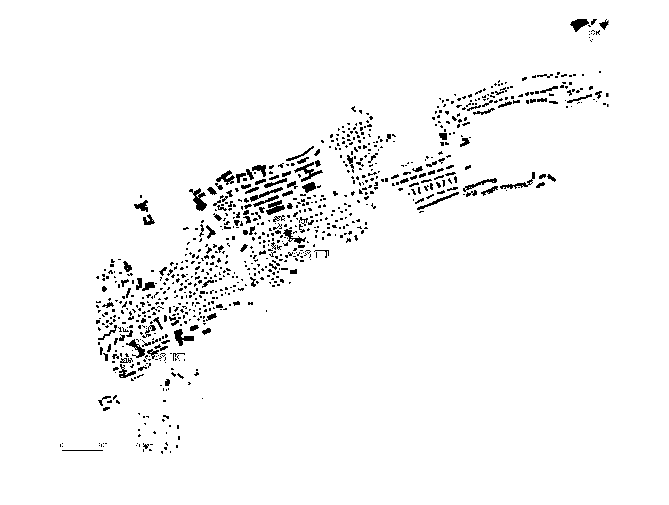

[rowb3,colb3] = find(abs(X)<1);
rgbColorb3 = impixel(b3img, colb3, rowb3);
Newimageb3 = X;
Fn78 = zeros(min(size(X)),max(size(X)),3);
Fn78(:,:,1) = X(:,:);
Fn78(:,:,2) = X(:,:);
Fn78(:,:,3) = X(:,:);

[X, map] = gray2ind(Igrn78, 64);
indices = find(abs(X)>35);
X(indices) = 255;
indices2 = find(abs(X)<35);
X(indices2) = 0;

imshow(X,map)

Newimagen78 = X;
[rown78,coln78] = find(abs(X)<1);
rgbColorn78 = impixel(n78img, coln78, rown78);
Fn78 = zeros(min(size(X)),max(size(X)),3);
Fn78(:,:,1) = X(:,:);
Fn78(:,:,2) = X(:,:);
Fn78(:,:,3) = X(:,:);


Threshold = -115;
Penloss2Lagn78 = -14.1;
Penloss3Lagn78 = -28.2;

Penloss2Lagb3 = -9.9;
Penloss3Lagb3 = -18.2;
GreenCount = 0;
RedCount = 0;
YelCount = 0;
BlueCount = 0;
redC =0;
brownC = 0;
YelC = 0;
GreenC = 0;
LightBlueC  = 0;
MidBlueC = 0;
DarkBlueC = 0;

size(rgbColorn78)

ans =        91604           3


size(rgbColorb3)

ans =        92667           3


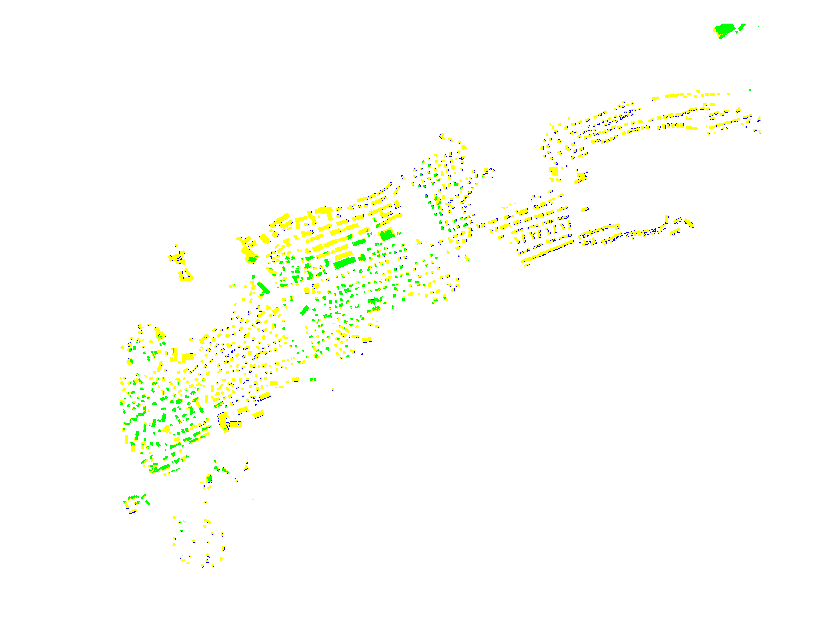


for x = 1:min(size(X)) 
    for y = 1:max(size(X))
 Signaln78 = -180;
 Signalb3 = -180;
            if n78img(x,y,1) == 128 && n78img(x,y,2) == 0
                redC = redC +1;
                Signaln78 = -70;
                fisk = 1;
            elseif n78img(x,y,1) == 127 && (n78img(x,y,2) == 84 || n78img(x,y,2) == 63) || n78img(x,y,2) == 97 || (n78img(x,y,1) == 127 && (n78img(x,y,2) == 84 || n78img(x,y,2) == 63 || n78img(x,y,2) == 94) && n78img(x,y,3) == 63)
                Signaln78 = -80;
                brownC = brownC +1;
                    fisk = 1;
            elseif (n78img(x,y,1) == 128 || n78img(x,y,1) == 127) && (n78img(x,y,2) == 128 || n78img(x,y,2) == 127)
                Signaln78 = -90;
                YelC = YelC +1;
        fisk = 1;
            elseif n78img(x,y,1) == 0 && n78img(x,y,2) == 128 && (n78img(x,y,3) == 0 || n78img(x,y,3) == 63)
                Signaln78 = -100;
                GreenC = GreenC +1;
            
fisk = 1;
            elseif n78img(x,y,2) == 128 && n78img(x,y,3) == 128
                Signaln78 = -110;
                LightBlueC = LightBlueC +1;
                fisk = 1;
            elseif n78img(x,y,2) == 128 && n78img(x,y,3) == 191
                Signaln78 = -120;
                MidBlueC = MidBlueC +1;
            fisk = 1;
            elseif n78img(x,y,3) == 128 && n78img(x,y,2) == 0
                Signaln78 = -130;
                DarkBlueC = DarkBlueC+1;
                fisk = 1;
            end

            if b3img(x,y,1) == 128 && b3img(x,y,2) == 0
                redC = redC +1;
                Signalb3 = -70;
            fisk = 1;
            elseif b3img(x,y,1) == 127 && (b3img(x,y,2) == 84 || b3img(x,y,2) == 63) || b3img(x,y,2) == 97 || (b3img(x,y,1) == 127 && (b3img(x,y,2) == 84 || b3img(x,y,2) == 63 || b3img(x,y,2) == 94) && b3img(x,y,3) == 63)
                Signalb3 = -80;
                brownC = brownC +1;
fisk = 1;
            elseif (b3img(x,y,1) == 128 || b3img(x,y,1) == 127) && (b3img(x,y,2) == 128 || b3img(x,y,2) == 127)
                Signalb3 = -90;
                YelC = YelC +1;
        fisk = 1;
            elseif b3img(x,y,1) == 0 && b3img(x,y,2) == 128 && (b3img(x,y,3) == 0 || b3img(x,y,3) == 63)
                Signalb3 = -100;
                GreenC = GreenC +1;
            
fisk = 1;
            elseif b3img(x,y,2) == 128 && b3img(x,y,3) == 128
                Signalb3 = -110;
                LightBlueC = LightBlueC +1;
                fisk = 1;
            elseif b3img(x,y,2) == 128 && b3img(x,y,3) == 191
                Signalb3 = -120;
                MidBlueC = MidBlueC +1;
            fisk = 1;
            elseif b3img(x,y,3) == 128 && b3img(x,y,2) == 0
                Signalb3 = -130;
                DarkBlueC = DarkBlueC+1;
                fisk = 1;

            end

                if (Signaln78+Penloss2Lagn78) > Threshold && fisk == 1 %3lags 3.5
                   Fn78(x,y,1) = 0;
                   Fn78(x,y,2) = 255;
                   Fn78(x,y,3) = 0;
                   GreenCount = GreenCount+1;
                
                elseif (Signalb3+Penloss2Lagb3) > Threshold && fisk == 1 %3lag 1.8
                   Fn78(x,y,1) = 255;
                   Fn78(x,y,2) = 255;
                   Fn78(x,y,3) = 0;
                   YelCount = YelCount+1;
                
                elseif (Signalb3) > Threshold && fisk == 1 %Outdoor uden pen
                   Fn78(x,y,1) = 0;
                   Fn78(x,y,2) = 0;
                   Fn78(x,y,3) = 255;
                   BlueCount = BlueCount+1;
                elseif b3img(x,y,1) == 0 && b3img(x,y,2) == 0 && b3img(x,y,3) == 0 && fisk == 1 % nothing
                   Fn78(x,y,1) = 255;
                   Fn78(x,y,2) = 0;
                   Fn78(x,y,3) = 0;
                   RedCount = RedCount+1;
                else
                   Fn78(x,y,1) = 255;
                   Fn78(x,y,2) = 255;
                   Fn78(x,y,3) = 255;

                end
fisk = 0;

    end
end
imshow(Fn78,map)

Totalcount = RedCount+GreenCount+YelCount+BlueCount

Totalcount = 84367

Y = [GreenCount/Totalcount*100 YelCount/Totalcount*100 BlueCount/Totalcount*100 RedCount/Totalcount*100]

Y =    20.7166   70.7670    8.4784    0.0379


Names = {'3LagPenLoss'; '2LagPenLoss'; 'Outdoor/Ingen PenLoss'; 'Intet signal';}

Names = 4×1 cell array
    {'3LagPenLoss'          }
    {'2LagPenLoss'          }
    {'Outdoor/Ingen PenLoss'}
    {'Intet signal'         }


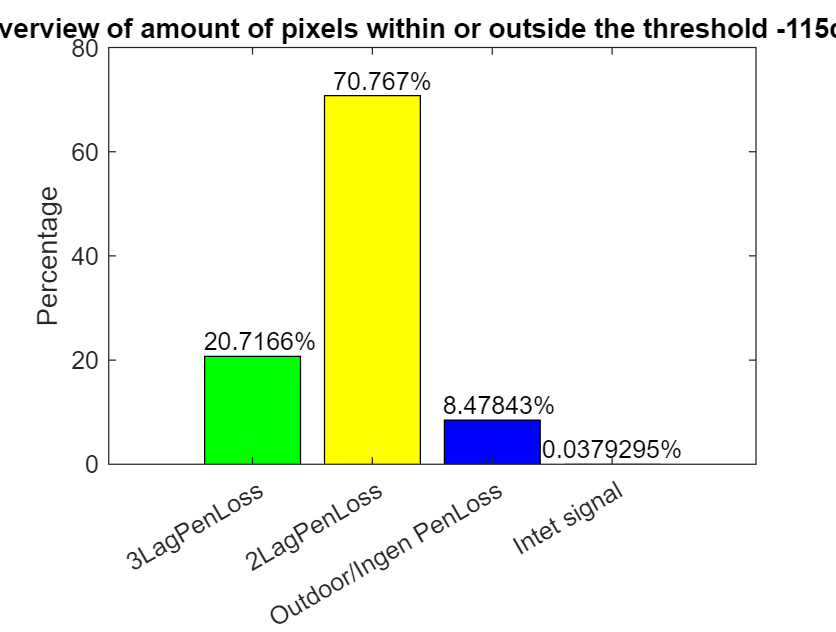

X = [1 2 3 4];
b = bar(X,Y);
b.FaceColor = 'flat';
b.CData(1,:) = [0 1 0];
b.CData(2,:) = [1 1 0];
b.CData(3,:) = [0 0 1];
b.CData(4,:) = [1 0 0];
set(gca,'xtick',[1:4],'xticklabel',Names);
ylabel('Percentage')
title('Overview of amount of pixels within or outside the threshold -115dbm')
text(1:length(Y),Y,num2str(Y')+"%",'vert','bottom','horiz','center'); 